# Read, Apply and Save the standard colormaps from IPCC

IPCC colormaps from GitHub® repository: [https://github.com/IPCC-WG1/colormaps](https://github.com/IPCC-WG1/colormaps) 

Author: Kostas Leptokaropoulos

*"Copyright 2024 - 2025, The MathWorks, Inc." *

clear vars; close all


## 1. Select type of colormap from the drop down menu: '*Continuous*', '*Categorical*' or '*Discrete*'

Type = "discrete" ; 

% Test figure
[X, Y, Z] = peaks(40);
figure;


switch Type

### 2. Continuous **Colormap**

    case "continuous" 
    disp('Continuous Colormap Chosen')

#### Select the name of the Continuous colormap

% Define the URL
url = "https://raw.githubusercontent.com/IPCC-WG1/colormaps/refs/heads/master/continuous_colormaps_rgb_0-255/chem_div.txt";

A =  webread(url);
A = str2num(A);
cmap = colormap(uint8(A));

    

### 2. Categorical Colormap

    case "categorical"
        disp('Categorical Colormap Chosen')   

####   Select the name of the Categorical colormap

url = "https://raw.githubusercontent.com/IPCC-WG1/colormaps/refs/heads/master/categorical_colors_rgb_0-255/bright_cat.txt";

A =  webread(url);
A = str2num(A);
cmap = colormap(uint8(A));

### 2. Discrete Colormap

    case "discrete"
    disp('Discrete Colormap Chosen')

#### Select the name of the Discrete colormap

url =  ("https://raw.githubusercontent.com/IPCC-WG1/colormaps/refs/heads/master/discrete_colormaps_rgb_0-255/temp_div_disc.txt");
chac = char(url) ;
A = webread(url) ;
data = textscan(A, '%s', 'Delimiter', '\n');


#### 2a. Set the number of intervals in the colormap *(5 to 20)*

          numberC = 20;


% Convert the cell array to a string array for easier processing
data = string(data{1});

% Initialize a structure to hold the colormaps
colormaps = struct();

% Temporary variables to store the current colormap name and RGB values
currentMap = '';
currentColors = [];

for i = 1:length(data)
    line = data(i);
    if startsWith(line, chac(101:end-9))
        % Save the previous colormap if there is one
        if ~isempty(currentMap)
            colormaps.(currentMap) = currentColors / 1; % divide by 255 to Normalize RGB values
        end
        % Start a new colormap
        currentMap = line;
        currentColors = [];
    else
        % Add the RGB values to the current colormap
        rgb = sscanf(line, '%d %d %d');
        currentColors = [currentColors; rgb'];
    end
end

FN = fieldnames(colormaps);
cmap = colormap(uint8(colormaps.(FN{numberC-4})));

end

Discrete Colormap Chosen


### **3. Save the colormap as its original name**

% Extract the filename using split
[~, filename, ext] = fileparts(url);
% Combine filename and extension
filename_with_ext = filename + ext;
% Save colormap as a text file
writematrix(cmap, filename_with_ext);
disp(['Colormap saved as ', filename_with_ext]);

    "Colormap saved as "    "temp_div_disc.txt"



### **4. Plot an example with the selected colormap**

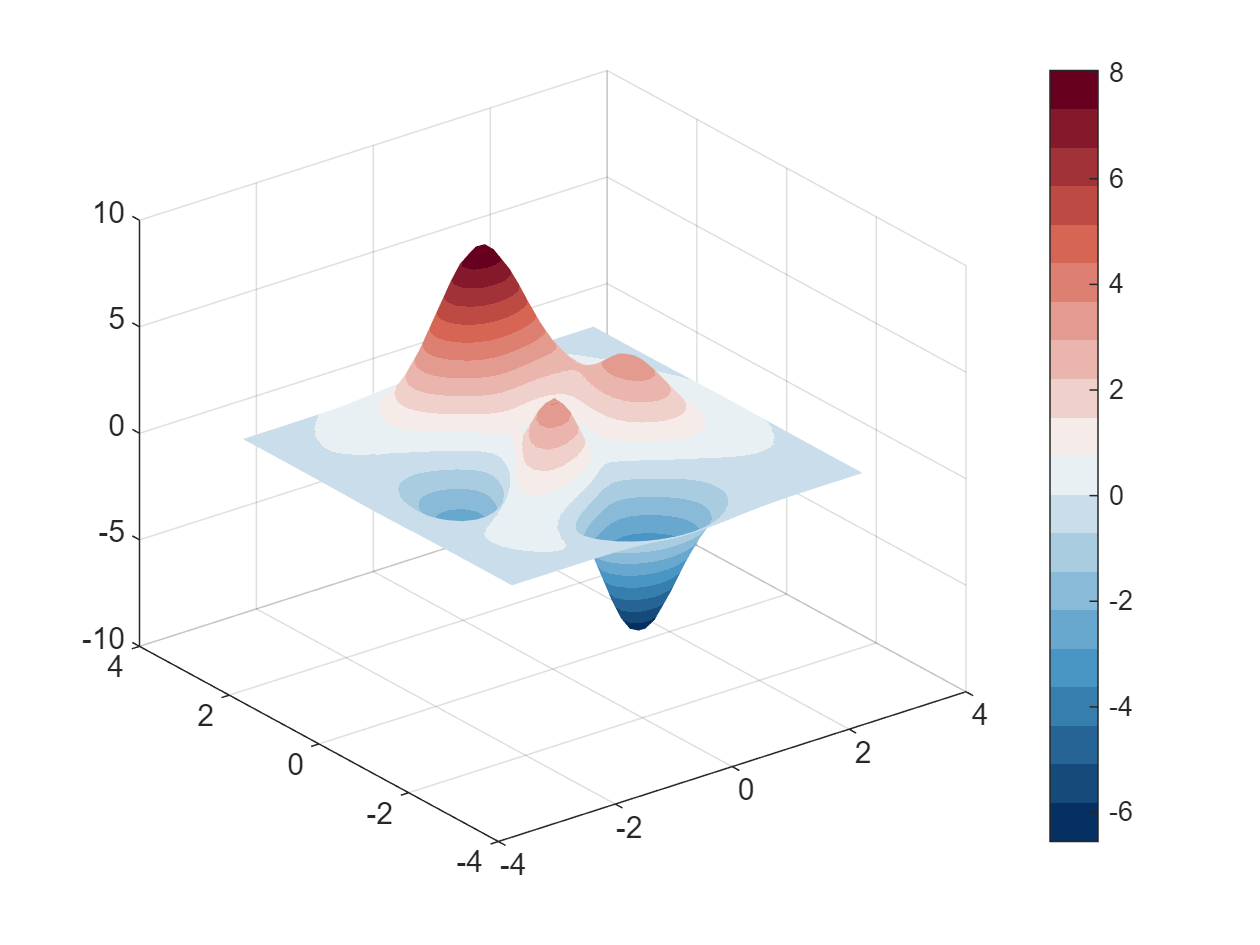

surf(X, Y, Z);
interpolated_color = true;
if interpolated_color;shading interp;end
colorbar       

cmap

cmap = 20×3 uint8 matrix
     5    48    97
    21    74   122
    37   100   148
    53   126   174
    73   150   196
   105   168   206
   137   186   215
   169   204   225
   201   222   234
   233   240   244


### You can then import the saved colormaps anytime as the following script 

*please uncomment and modify accordingly*

% cmap = uint8(readmatrix("misc_seq_3.txt"));
% colorbar
% colormap(cmap)

*"Copyright 2024 - 2025, The MathWorks, Inc." *